Comparing the number of spikes to the first flash with the number of spikes on the last flash to test if the maybe the epifluorescent light influences this

% downs = grabFromFilter('Downs', 'ExcludeSingleLabels');
% ups = grabFromFilter('Ups', 'ExcludeSingleLabels');
ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');
allCells = [ups;downs];

%choose which protocols to look at
priorityOrder_1 = {'Flash'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; '_all'; 'Extracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %use only cells with LED spot diameter = 500

numFirstSpikes = [];
numLastSpikes = [];
timeIntervals = []; %amount of time between first and last epoch
coords = [];
lastIndexFound = 0;
g = waitbar(0, '')
for i = 1:size(allCells, 1)
    struct_i = allCells{i, 2};
    
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    
    preTime_i = loc.meta.preTime;
    stimTime_i = loc.meta.stimTime;
    tailTime_i = loc.meta.tailTime;
    
    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    try
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
    catch
        disp(['No coordinates for ' struct_i.cellID])
        continue
    end
    if i > size(ups, 1) && lastIndexFound == 0
        lastUpIndex = numel(numFirstSpikes); %write down where it switches from ups to downs
        lastIndexFound = 1;
    end
    numEpochs = numel(loc.Analysis_Results.allSpikeTimes);
    if numEpochs > 1
        coords = [coords; x, y];
        numFirstSpikes(end +1) = numel(loc.Analysis_Results.allSpikeTimes{1});
        numLastSpikes(end + 1) = numel(loc.Analysis_Results.allSpikeTimes{numEpochs});
        clarinetExport = getClarinetExport(struct_i);
        firstEpochTime = clarinetExport(loc.Analysis_Results.EpochNumbers(1)).meta.epochTime;
        lastEpochTime = clarinetExport(loc.Analysis_Results.EpochNumbers(end)).meta.epochTime;
        timeIntervals(end + 1) = minutes(lastEpochTime-firstEpochTime);
    end
end

No coordinates for SHOKR58Lc7


x_coords = -coords(:, 1);
y_coords = coords(:, 2);

differences = numLastSpikes - numFirstSpikes;
differenceIndex = (numLastSpikes - numFirstSpikes)./(numLastSpikes + numFirstSpikes);

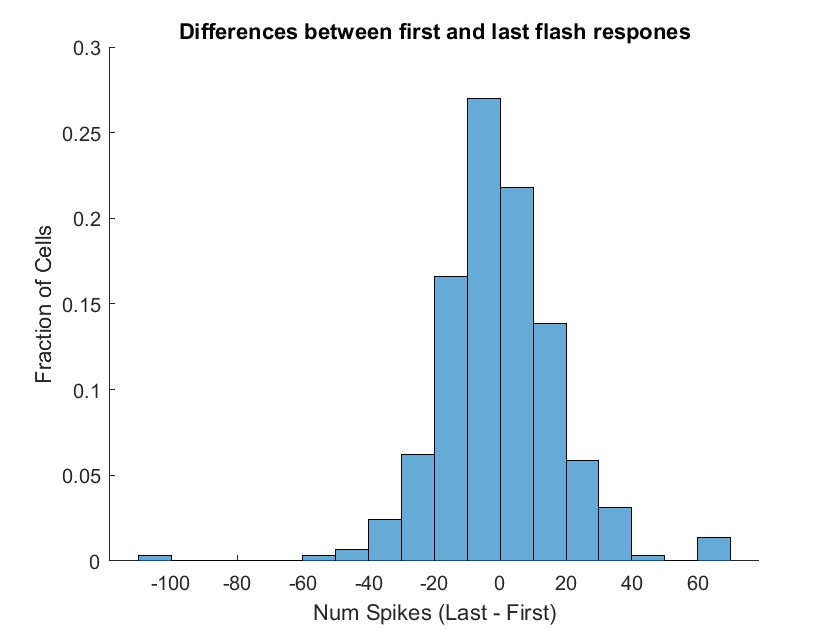

dorsalDifferences = differences(y_coords>0);
ventralDifferences = differences(y_coords<0);

figure
title('Differences between first and last flash respones')
hold on
histogram(differences, 'Normalization', 'probability')
xlabel('Num Spikes (Last - First)')
ylabel('Fraction of Cells')

p = signrank(differences)

p = 0.2163

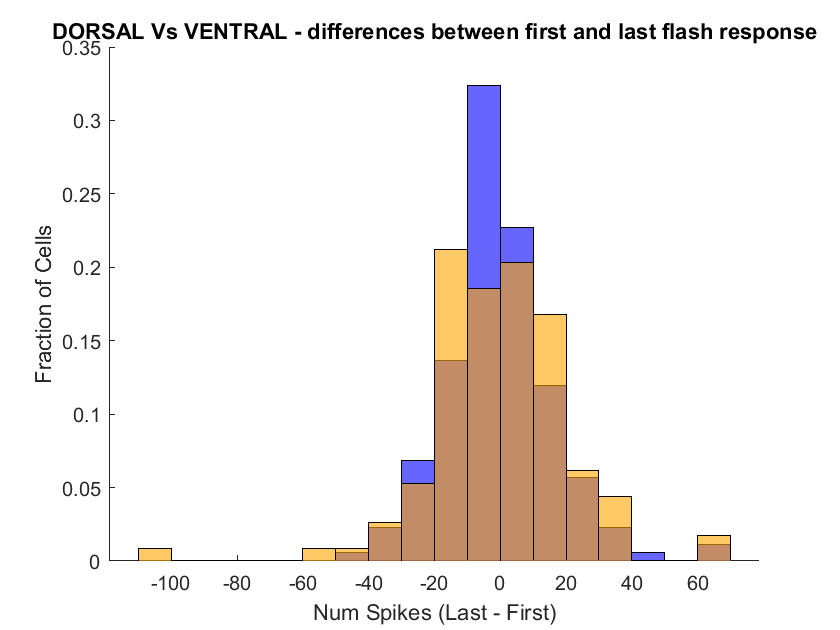


figure
title('DORSAL Vs VENTRAL - differences between first and last flash response')
hold on
h1 = histogram(dorsalDifferences, 'FaceColor', [0, 0, 255]./255, 'Normalization', 'probability');
h2 = histogram(ventralDifferences, 'FaceColor', [255, 165, 0]./255, 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('Num Spikes (Last - First)')
ylabel('Fraction of Cells')

p = ranksum(dorsalDifferences, ventralDifferences)

p = 0.8484

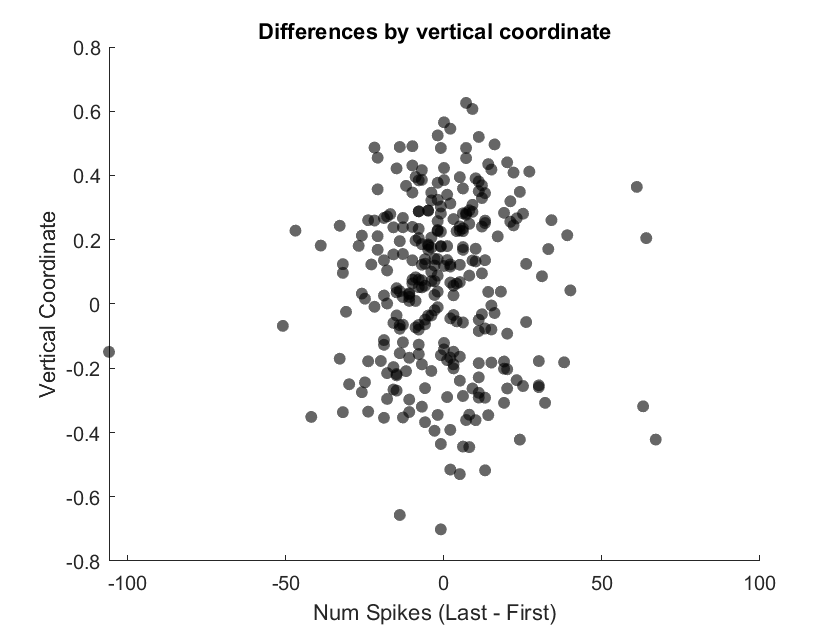

figure
title('Differences by vertical coordinate')
hold on
scatter(differences, y_coords, 'black', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('Num Spikes (Last - First)')
ylabel('Vertical Coordinate')

[r, p] = corr(differences', y_coords, 'type','Spearman')

r = 0.0555

p = 0.3471

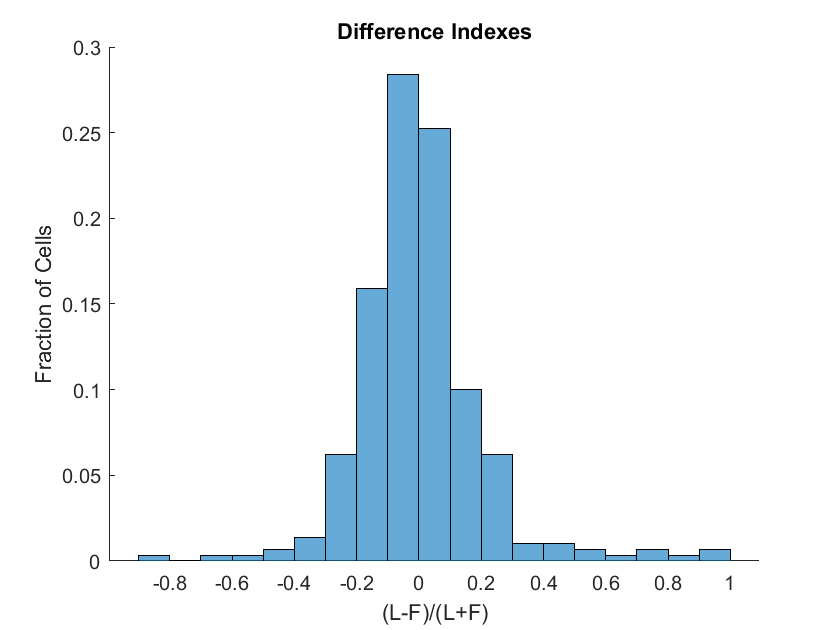


dorsalDiffIndexes = differenceIndex(y_coords>0);
ventralDifferencesIndexes = differenceIndex(y_coords<0);

figure
title('Difference Indexes')
hold on
histogram(differenceIndex, 'Normalization', 'probability')
xlabel('(L-F)/(L+F)')
ylabel('Fraction of Cells')

p = signrank(differenceIndex)

p = 0.2915

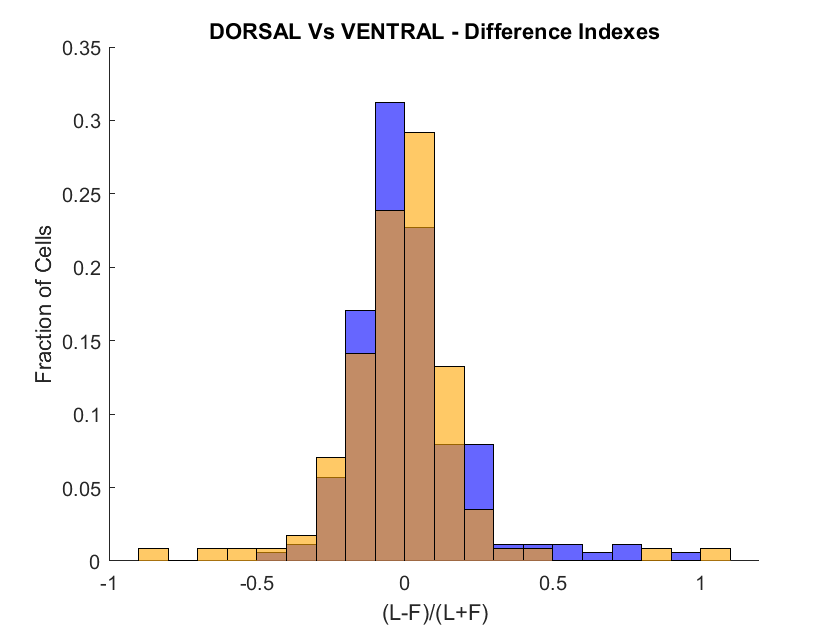


figure
title('DORSAL Vs VENTRAL - Difference Indexes')
hold on
h1 = histogram(dorsalDiffIndexes, 'FaceColor', [0, 0, 255]./255, 'Normalization', 'probability');
h2 = histogram(ventralDifferencesIndexes, 'FaceColor', [255, 165, 0]./255, 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('(L-F)/(L+F)')
ylabel('Fraction of Cells')

p = ranksum(dorsalDiffIndexes, ventralDifferencesIndexes)

p = 0.8876

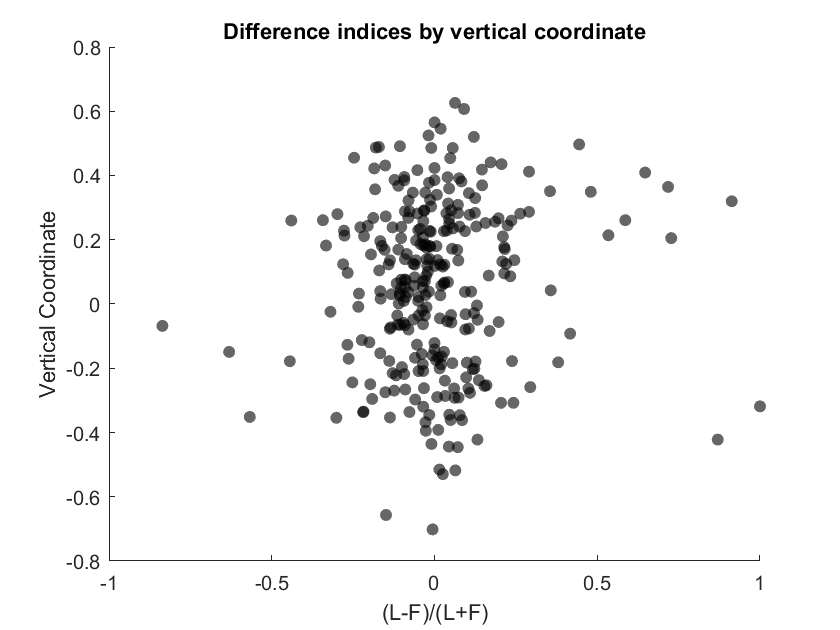

figure
title('Difference indices by vertical coordinate')
hold on
scatter(differenceIndex, y_coords, 'black', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('(L-F)/(L+F)')
ylabel('Vertical Coordinate')

[r, p] = corr(differenceIndex', y_coords, 'type','Spearman')

r = 0.0651

p = 0.2702

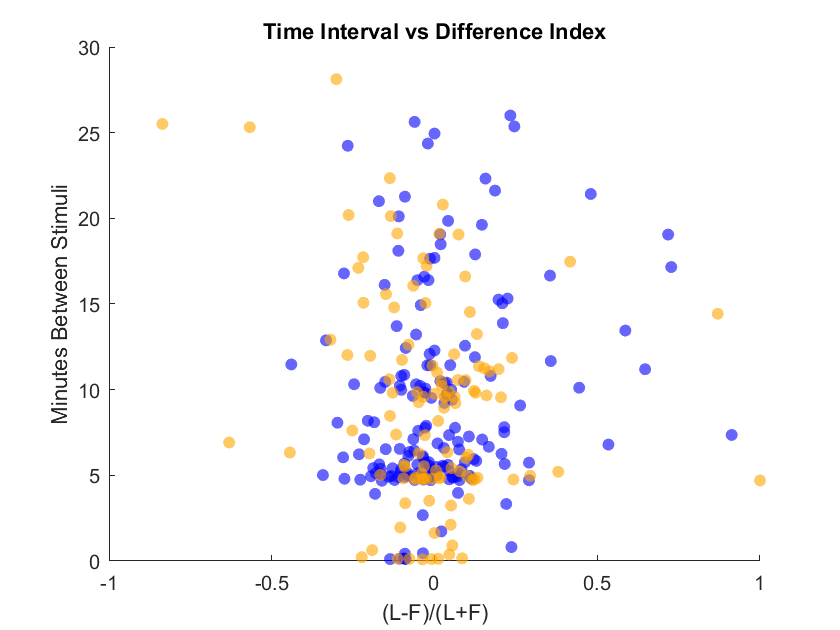

dorsalIntervals = timeIntervals(y_coords>0);
ventralIntervals = timeIntervals(y_coords<0);
figure
title('Time Interval vs Difference Index')
hold on
scatter(dorsalDiffIndexes, dorsalIntervals, 'filled', 'MarkerFaceColor', [0, 0, 255]./255, 'MarkerFaceAlpha', 0.6)
scatter(ventralDifferencesIndexes, ventralIntervals, 'filled', 'MarkerFaceColor', [255, 165, 0]./255,'MarkerFaceAlpha', 0.6)
ylabel('Minutes Between Stimuli')
xlabel('(L-F)/(L+F)')
ylim([0 30])

[r_dorsal, p_dorsal] = corr(dorsalDiffIndexes', dorsalIntervals', 'type','Spearman')

r_dorsal = 0.1917

p_dorsal = 0.0108

[r_ventral, p_ventral] = corr(ventralDifferencesIndexes', ventralIntervals', 'type','Spearman')

r_ventral = -0.1358

p_ventral = 0.1514

## total first spikes

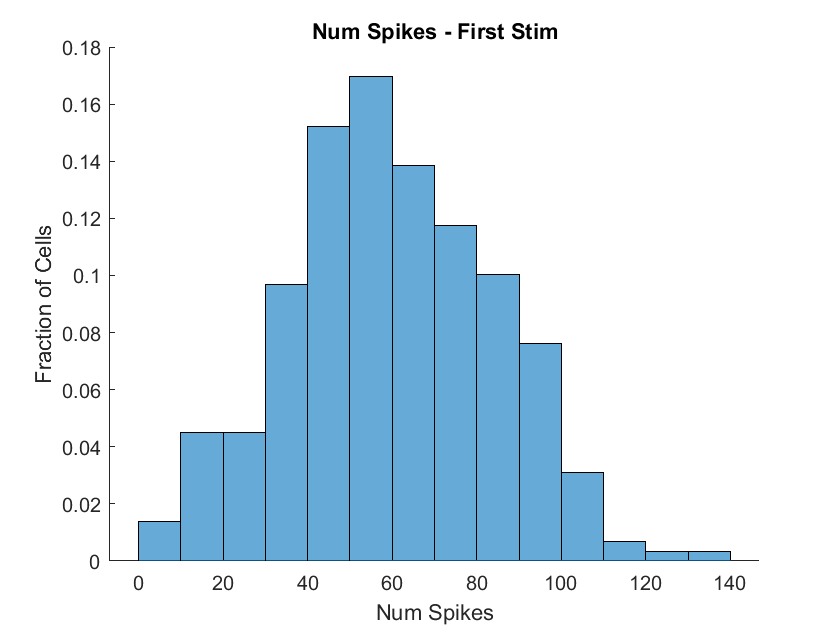

dorsalFirstSpikes = numFirstSpikes(y_coords>0.25);
ventralFirstSpikes = numFirstSpikes(y_coords<0);


figure
title('Num Spikes - First Stim')
hold on
histogram(numFirstSpikes, 'Normalization', 'probability')
xlabel('Num Spikes')
ylabel('Fraction of Cells')

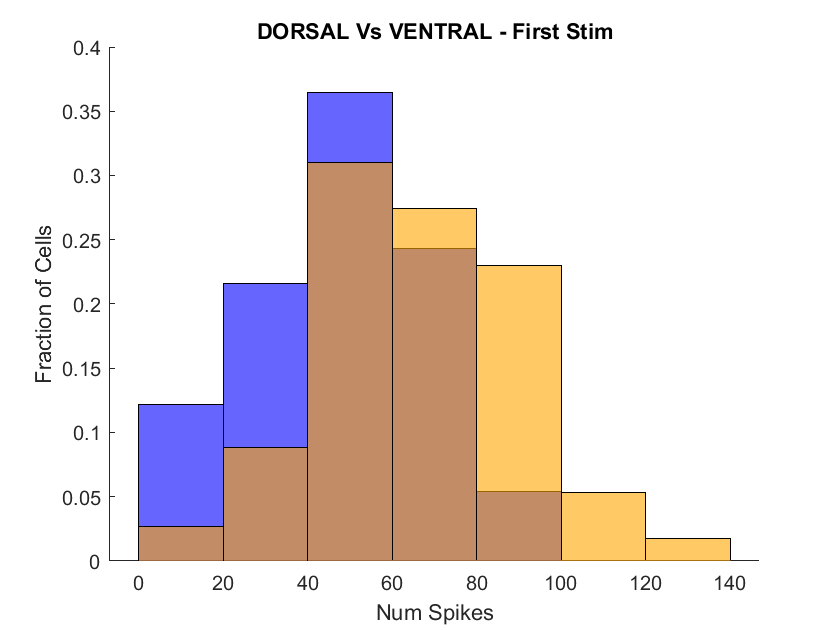


figure
title('DORSAL Vs VENTRAL - First Stim')
hold on
h1 = histogram(dorsalFirstSpikes, 'FaceColor', [0, 0, 255]./255, 'Normalization', 'probability');
h2 = histogram(ventralFirstSpikes, 'FaceColor', [255, 165, 0]./255, 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('Num Spikes')
ylabel('Fraction of Cells')

p = ranksum(dorsalFirstSpikes, ventralFirstSpikes)

p = 5.3845e-08

## total last spikes

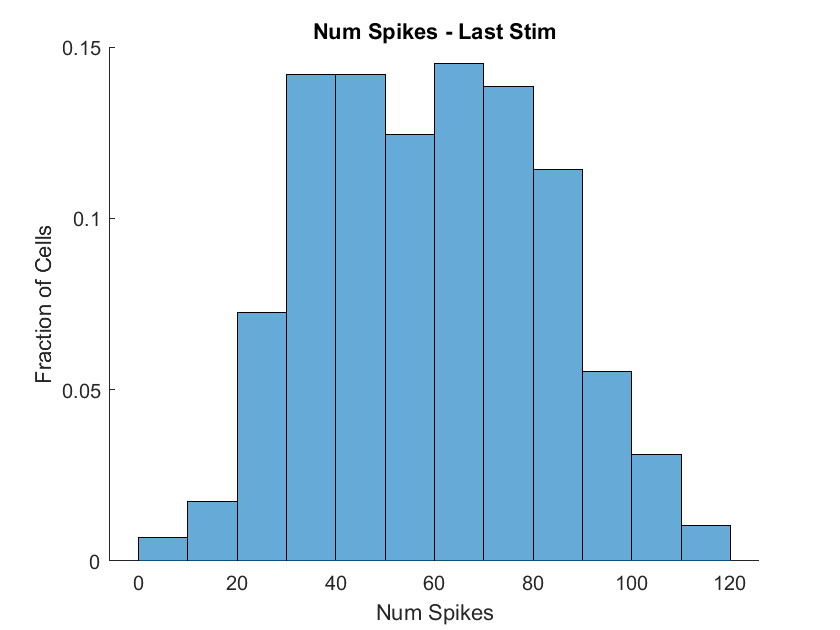

dorsalLastSpikes = numLastSpikes(y_coords>0);
ventralLastSpikes = numLastSpikes(y_coords<0);

figure
title('Num Spikes - Last Stim')
hold on
histogram(numLastSpikes, 'Normalization', 'probability')
xlabel('Num Spikes')
ylabel('Fraction of Cells')

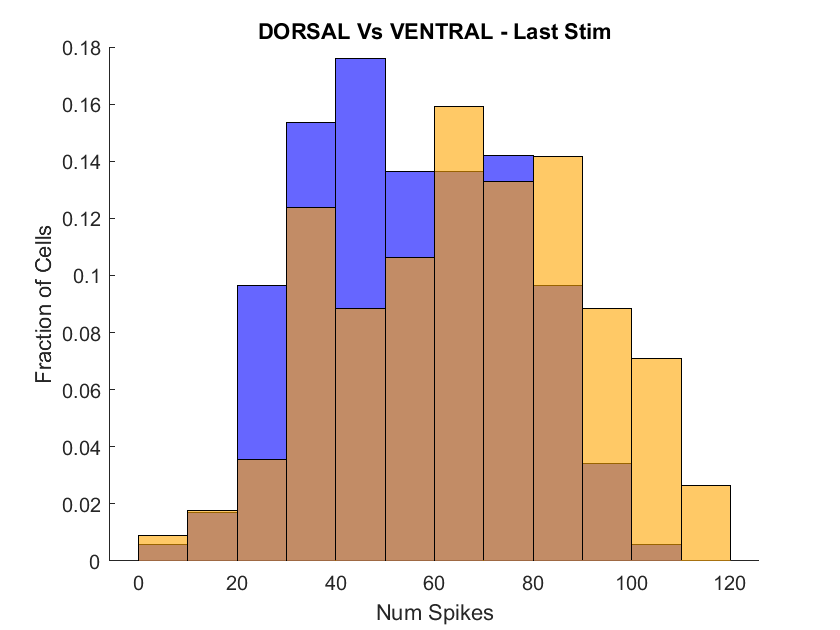


figure
title('DORSAL Vs VENTRAL - Last Stim')
hold on
h1 = histogram(dorsalLastSpikes, 'FaceColor', [0, 0, 255]./255, 'Normalization', 'probability');
h2 = histogram(ventralLastSpikes, 'FaceColor', [255, 165, 0]./255, 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('Num Spikes')
ylabel('Fraction of Cells')

p = ranksum(dorsalLastSpikes, ventralLastSpikes)

p = 6.2280e-05

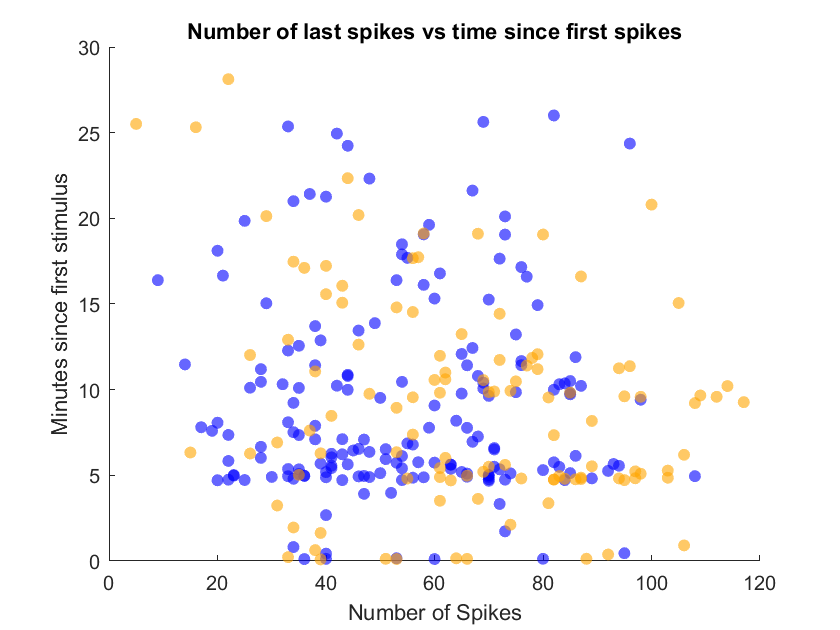


figure
title('Number of last spikes vs time since first spikes')
hold on
scatter(dorsalLastSpikes, dorsalIntervals, 'filled', 'MarkerFaceColor', [0, 0, 255]./255,'MarkerFaceAlpha', 0.6)
scatter(ventralLastSpikes, ventralIntervals, 'filled', 'MarkerFaceColor', [255, 165, 0]./255,'MarkerFaceAlpha', 0.6)
xlabel('Number of Spikes')
ylabel('Minutes since first stimulus')
ylim([0 30])

[r_dorsal, p_dorsal] = corr(dorsalLastSpikes', dorsalIntervals', 'type','Spearman')

r_dorsal = 0.0044

p_dorsal = 0.9541

[r_ventral, p_ventral] = corr(ventralLastSpikes', ventralIntervals', 'type','Spearman')

r_ventral = -0.1957

p_ventral = 0.0378

## Up vs Down Cells

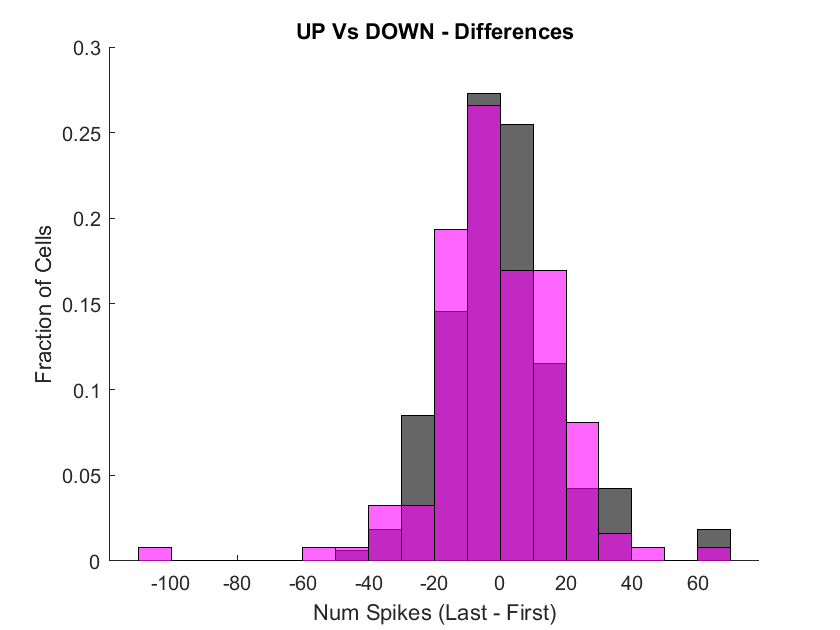

upDifferences = differences(1:lastUpIndex);
downDifferences = differences(lastUpIndex+1:end);

figure
title('UP Vs DOWN - Differences')
hold on
h1 = histogram(upDifferences, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downDifferences, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('Num Spikes (Last - First)')
ylabel('Fraction of Cells')

p = ranksum(upDifferences, downDifferences)

p = 0.9824

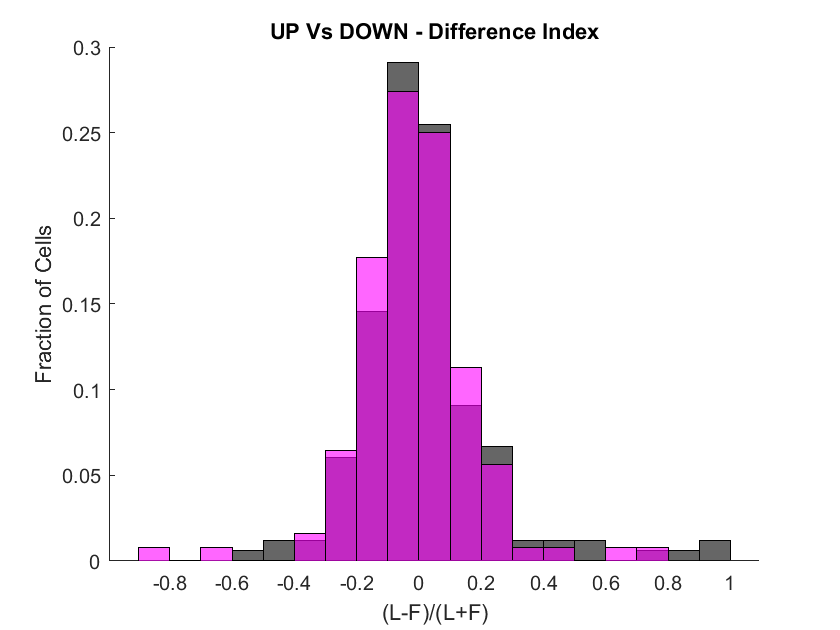


upDifferenceIndexes = differenceIndex(1:lastUpIndex);
downDifferenceIndexes = differenceIndex(lastUpIndex+1:end);

figure
title('UP Vs DOWN - Difference Index')
hold on
h1 = histogram(upDifferenceIndexes, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downDifferenceIndexes, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('(L-F)/(L+F)')
ylabel('Fraction of Cells')

p = ranksum(upDifferenceIndexes, downDifferenceIndexes)

p = 0.5661

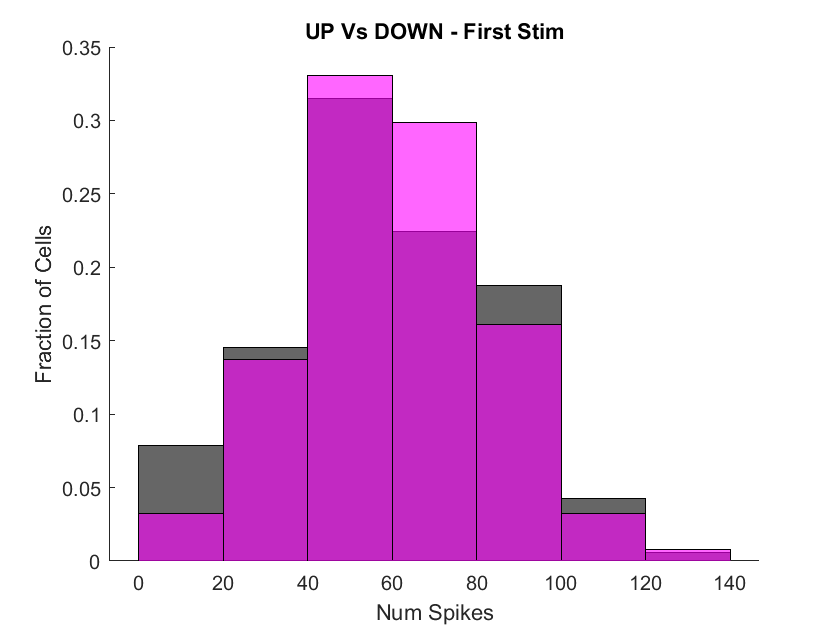


upFirstSpikes = numFirstSpikes(1:lastUpIndex);
downFirstSpikes = numFirstSpikes(lastUpIndex+1:end);

figure
title('UP Vs DOWN - First Stim')
hold on
h1 = histogram(upFirstSpikes, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downFirstSpikes, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('Num Spikes')
ylabel('Fraction of Cells')

p = ranksum(upFirstSpikes, downFirstSpikes)

p = 0.4574

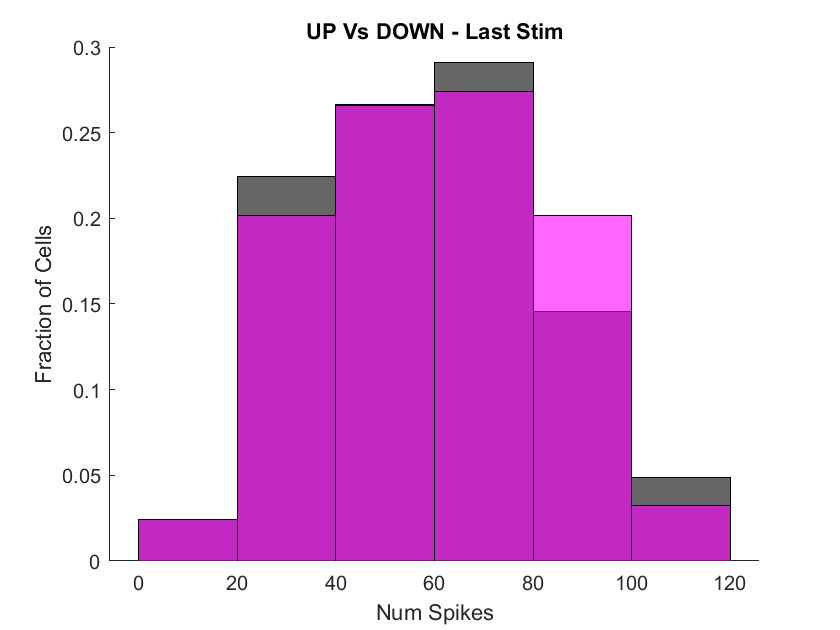


upLastSpikes = numLastSpikes(1:lastUpIndex);
downLastSpikes = numLastSpikes(lastUpIndex+1:end);

figure
title('UP Vs DOWN - Last Stim')
hold on
h1 = histogram(upLastSpikes, 'FaceColor', 'k', 'Normalization', 'probability');
h2 = histogram(downLastSpikes, 'FaceColor', 'm', 'FaceAlpha', 0.6, 'Normalization', 'probability');
h2.BinWidth = h1.BinWidth;
xlabel('Num Spikes')
ylabel('Fraction of Cells')

p = ranksum(upLastSpikes, downLastSpikes)

p = 0.5665

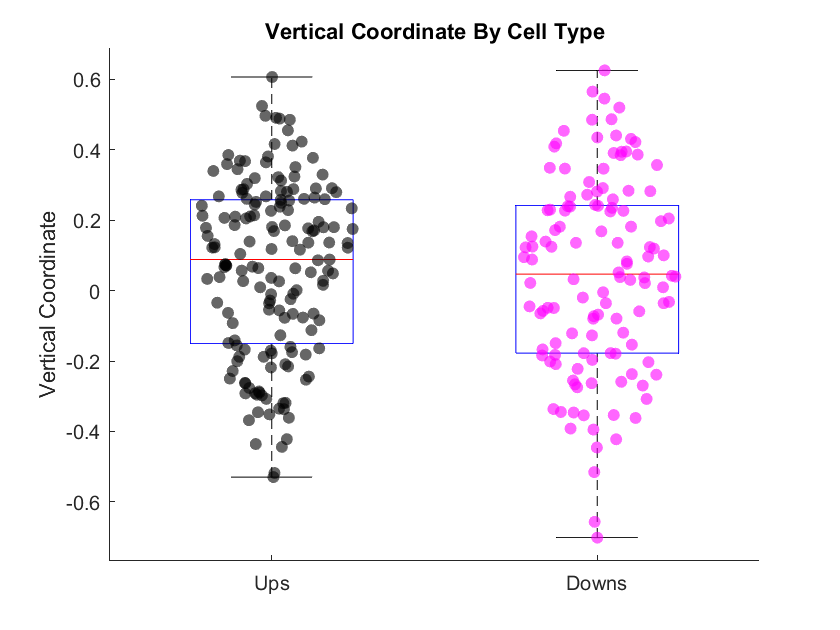

yCoords_up = y_coords(1:lastUpIndex);
yCoords_down = y_coords(lastUpIndex+1:end);

allPoints = [yCoords_up; yCoords_down];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(yCoords_up); 
groupIDs(indx1 + 1:end) = 1;


figure
title ('Vertical Coordinate By Cell Type')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(yCoords_up)), yCoords_up,'filled', 'MarkerFaceColor', 'k', 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(yCoords_down))+1, yCoords_down,'filled', 'MarkerFaceColor', 'm', 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Ups', 'Downs'})
ylabel('Vertical Coordinate')
box off

p = ranksum(yCoords_up, yCoords_down)

p = 0.6187

fractionUp = sum(yCoords_up>0)/numel(yCoords_up)

fractionUp = 0.6364

fractionDown = sum(yCoords_down>0)/numel(yCoords_down)

fractionDown = 0.5726

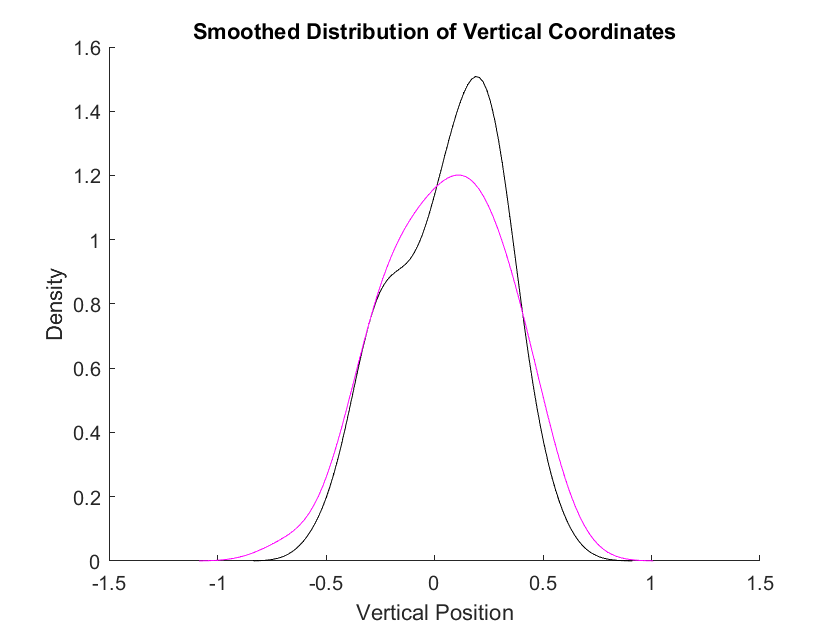

[f_up, xi_up] = ksdensity(yCoords_up);
[f_down, xi_down] = ksdensity(yCoords_down);
figure
title('Smoothed Distribution of Vertical Coordinates')
hold on
plot(xi_up, f_up, 'k')
plot(xi_down, f_down, 'm')
xlabel('Vertical Position')
ylabel('Density')